% Load the training data
data = load("aug4signs_trainingdata_new.mat");
signsDataset = data.trainingData;

% Split the dataset into training, validation, and test sets
rng(0); % Set random seed for reproducibility
shuffledIndices = randperm(height(signsDataset));
splitRatio = [0.6, 0.1, 0.3]; % Train, Validation, Test split ratios
numSamples = length(shuffledIndices);

% Calculate split indices
trainEndIdx = floor(splitRatio(1) * numSamples);
valEndIdx = trainEndIdx + floor(splitRatio(2) * numSamples);

% Split the data
trainingDataTbl = signsDataset(shuffledIndices(1:trainEndIdx), :);
validationDataTbl = signsDataset(shuffledIndices(trainEndIdx+1:valEndIdx), :);
testDataTbl = signsDataset(shuffledIndices(valEndIdx+1:end), :);


% Create datastores for images and labels
imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'TrafficSign'));

imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:,'TrafficSign'));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'TrafficSign'));

% Combine image and box label datastores
trainingData = combine(imdsTrain, bldsTrain);
validationData = combine(imdsValidation, bldsValidation);
testData = combine(imdsTest, bldsTest);

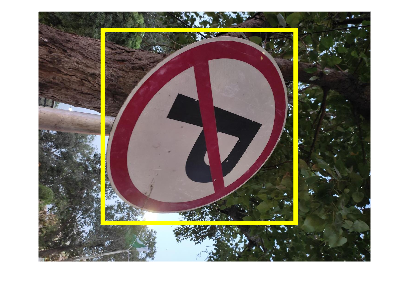


% Display a sample training image with bounding boxes
sampleData = read(trainingData);
sampleImage = sampleData{1};
sampleBoxes = sampleData{2};
annotatedImage = insertShape(sampleImage, 'rectangle', sampleBoxes,'LineWidth',18);
annotatedImage = imresize(annotatedImage, 2); % Resize for display
figure
imshow(annotatedImage)


% Create a Faster R-CNN detection network
inputSize = [224 224 3];
preprocessedTrainingData = transform(trainingData, @(data)preprocessData(data, inputSize));
numAnchors = 3;
anchorBoxes = estimateAnchorBoxes(preprocessedTrainingData, numAnchors);

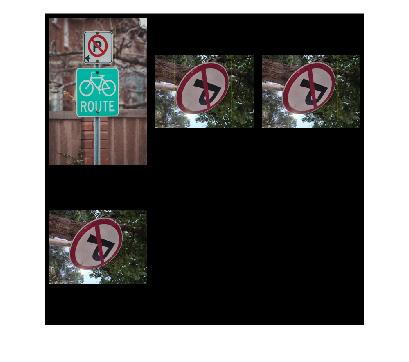


% Load a pretrained feature extraction network (ResNet-18)
featureExtractionNetwork = resnet18;
featureLayer = 'res4b_relu';
numClasses = width(signsDataset) - 1; % Exclude the background class
lgraph = fasterRCNNLayers(inputSize, numClasses, anchorBoxes, featureExtractionNetwork, featureLayer);

% Data augmentation for training
% augmentedTrainingData = transform(trainingData, @augmentData);
augmentedTrainingData = trainingData;

% Display augmented training data
displayAugmentedData(augmentedTrainingData);

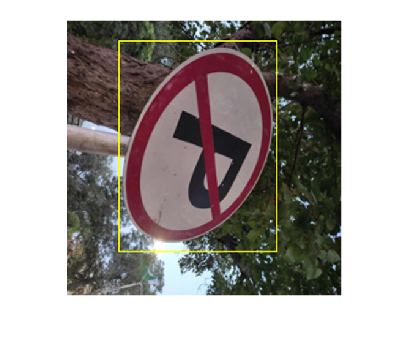


% Preprocess training and validation data
trainingData = transform(augmentedTrainingData, @(data)preprocessData(data, inputSize));
validationData = transform(validationData, @(data)preprocessData(data, inputSize));

% Display a sample preprocessed training image with bounding boxes
sampleData = read(trainingData);
sampleImage = sampleData{1};
sampleBoxes = sampleData{2};
annotatedImage = insertShape(sampleImage, 'rectangle', sampleBoxes);
annotatedImage = imresize(annotatedImage, 2); % Resize for display
figure
imshow(annotatedImage)

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* TrafficSign

Training on single CPU.
Initializing input data normalization.
|==========================================================================================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  RPN Mini-batch  |  RPN Mini-batch  |  Validation  |  Validation  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |     Accuracy     |       RMSE       |     Loss     |   Accuracy   |     RMSE     |      Rate       |
|==========================================================================================================================================================================================|
|       1 |      

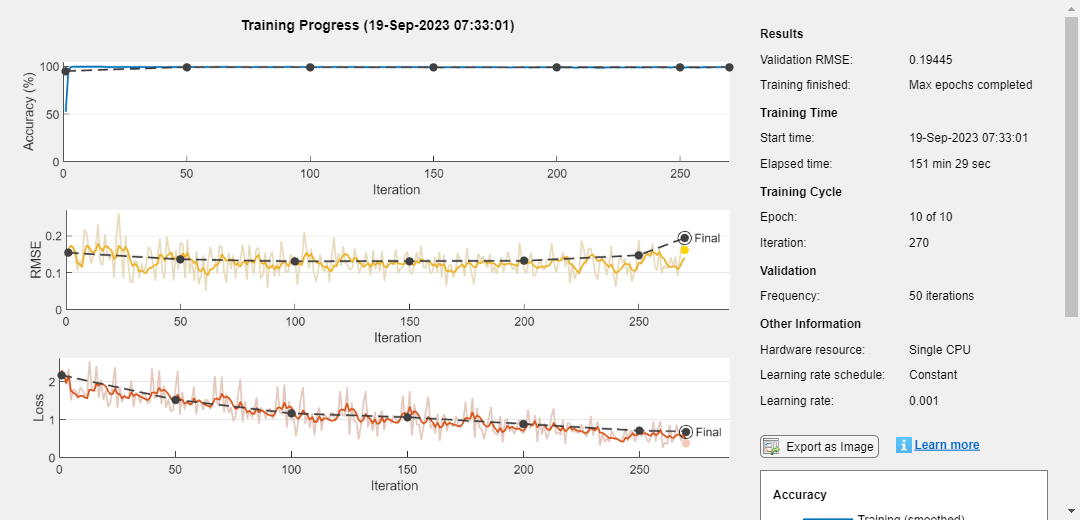

Detector training complete.
*******************************************************************





% Training options
options = trainingOptions('sgdm',...
    'MaxEpochs', 10,...
    'MiniBatchSize', 2,...
    'InitialLearnRate', 1e-3,...
    'Plots','training-progress',...
    'Verbose',true,...
    'VerboseFrequency',1,...
    'ValidationData', validationData...
);

% Train the Faster R-CNN detector
[detector, info] = trainFasterRCNNObjectDetector(trainingData, lgraph, options, ...
    'NegativeOverlapRange', [0 0.3], ...
    'PositiveOverlapRange', [0.6 1]);

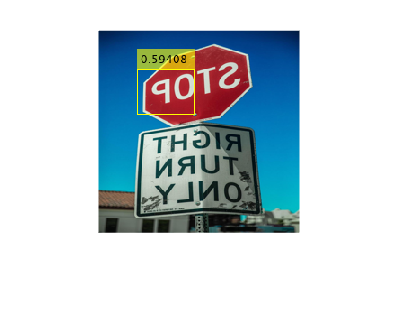

% Save the detector
save('fast_rcnn_resnet18_Detector_aug4signs_10e.mat', 'detector');

% Test the detector on a sample image
I = imread(testDataTbl.imageFilename{1});
I = imresize(I, inputSize(1:2));
[bboxes, scores] = detect(detector, I);

% Display the detection results
I = insertObjectAnnotation(I, 'rectangle', bboxes, scores);
figure
imshow(I)

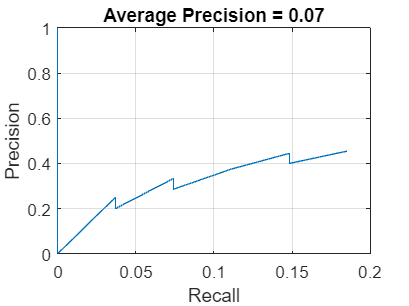



% Evaluate the detector using the test set
testData = transform(testData, @(data)preprocessData(data, inputSize));
detectionResults = detect(detector, testData, 'MinibatchSize', 4);
[ap, recall, precision] = evaluateDetectionPrecision(detectionResults, testData);

% Plot the precision-recall curve
figure
plot(recall, precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f', ap))

% Supporting data augmentation function

function data = augmentData(data)

% Randomly flip images and bounding boxes horizontally
tform = randomAffine2d('XReflection', true);
sz = size(data{1});
rout = affineOutputView(sz, tform);
data{1} = imwarp(data{1}, tform, 'OutputView', rout);

% Warp boxes
data{2} = bboxwarp(data{2}, tform, rout);
end

% Supporting data preprocessing function
function data = preprocessData(data, targetSize)
% Resize image and bounding boxes to targetSize
sz = size(data{1}, [1 2]);
scale = targetSize(1:2) ./ sz;
data{1} = imresize(data{1}, targetSize(1:2));

% Resize boxes
data{2} = bboxresize(data{2}, scale);
end

% Supporting function to display augmented data
function displayAugmentedData(data)
% Read and display the same image multiple times with augmentation
augmentedData = cell(4, 1);
for k = 1:4
    dataSample = read(data);
    augmentedImage = insertShape(dataSample{1}, 'rectangle', dataSample{2});
    augmentedImage = imresize(augmentedImage, 2); % Resize for display
    augmentedData{k} = augmentedImage;
    reset(data);
end
figure
montage(augmentedData, 'BorderSize', 10)
end
